clc; close all; clear all;

# **Lab 7**

**Event selection optimization.**

 You and your lab partner should pick *different* pT (transverse  momentum) samples (one uses low-pT sampels and the other use high-pT  samples) for this lab. In each pT sample, there are dedicated training  samples for event selection optimization. All studies should be carried  out by normalizing Higgs and QCD samples in each pT sample to given  expected yields accordingly (See Dataset descriptions).

I chose 250-500 datasets.

h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgData = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcdData = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

**Problem 1**

Make a stacked histogram plot for the feature variable: mass  

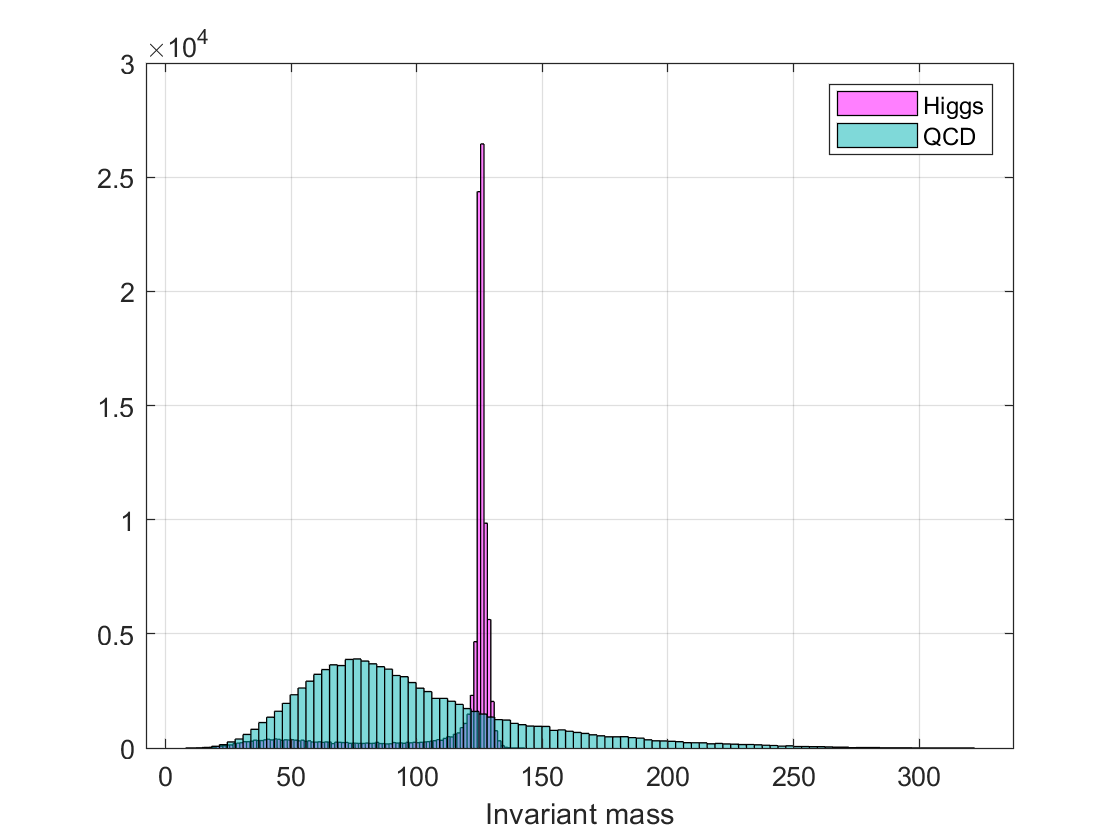

hInvariantMass = higgData(4,:);
histogram(hInvariantMass,100,'FaceColor',[1,0,1],'FaceAlpha',0.5);
xlabel 'Invariant mass'
hold on
grid on
qcdInvariantMass = qcdData(4,:);
histogram(qcdInvariantMass,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5);
legend("show","Higgs","QCD","Location","northeast")
hold off

Evaluate expected significance without any event selection.

- Use Poisson statistics for significance calculation

Assume the data is Poisson distributed

Since the data is not perfectly Poisson, we can get the median (lambda) from the histogram.

lambdaHiggs = 126;
lambdaQCD = 76;

- Compare your number of *NHiggs*/(√*NQCD*)

Nhiggs = 100; Nqcd = 20000;
ratio = Nhiggs/sqrt(Nqcd)

ratio = 0.7071

If they are equivalent, explain your findings.    They are not equivalent since their ratio is 0.707

The ration is 0.7 which means that there are 100 Higgs events for every 20000 QCD events. We need to optimize that we need to make the ratio above greater than 1.

**Problem 2.**

Normalize the distributions

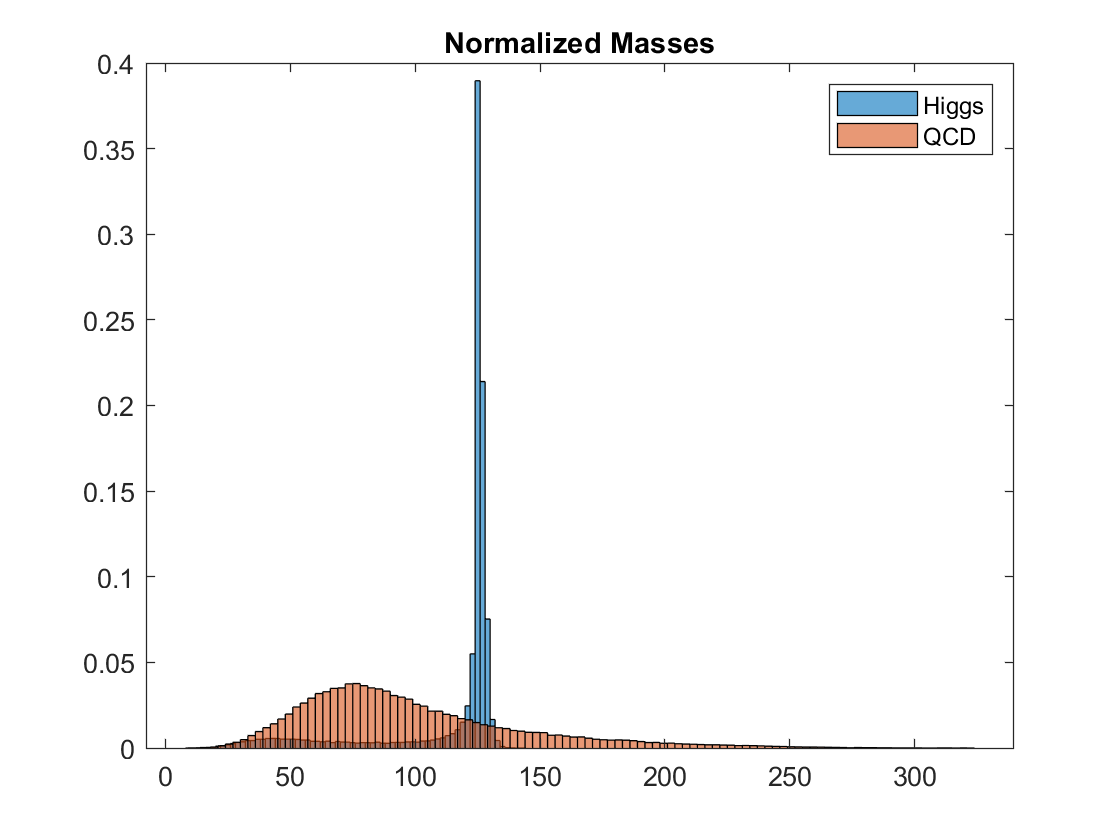

histogram(hInvariantMass,"Normalization","Probability")
hold on
histogram(qcdInvariantMass,"Normalization","Probability")
title 'Normalized Masses'
legend("show","Higgs","QCD","Location","northeast")
hold off

Make Poisson distributions with the given lambda values

pd_qcd = makedist('Poisson', 76);
pd_higgs = makedist('Poisson', 125);
t = 1;
fun = @(t) -1*(100*(cdf(pd_higgs,125+t)-cdf(pd_higgs,125-t)))/sqrt(abs(20000*(cdf(pd_qcd,125+t)-cdf(pd_qcd,125-t))));

newRatio = fun(t);
for t = 2:.1:100
    difference = abs(fun(t)-newRatio);
    newRatio = fun(t);
    if difference<=0.0000000000000000000000000000000001
        cut = t;
        break
    end
end
cut

cut = 2.2000

newRatio

newRatio = -193.8641

The most efficient cut seems to be in a range [122.8,127.2] that's where our significance (newRatio) is highest.

Make cuts:

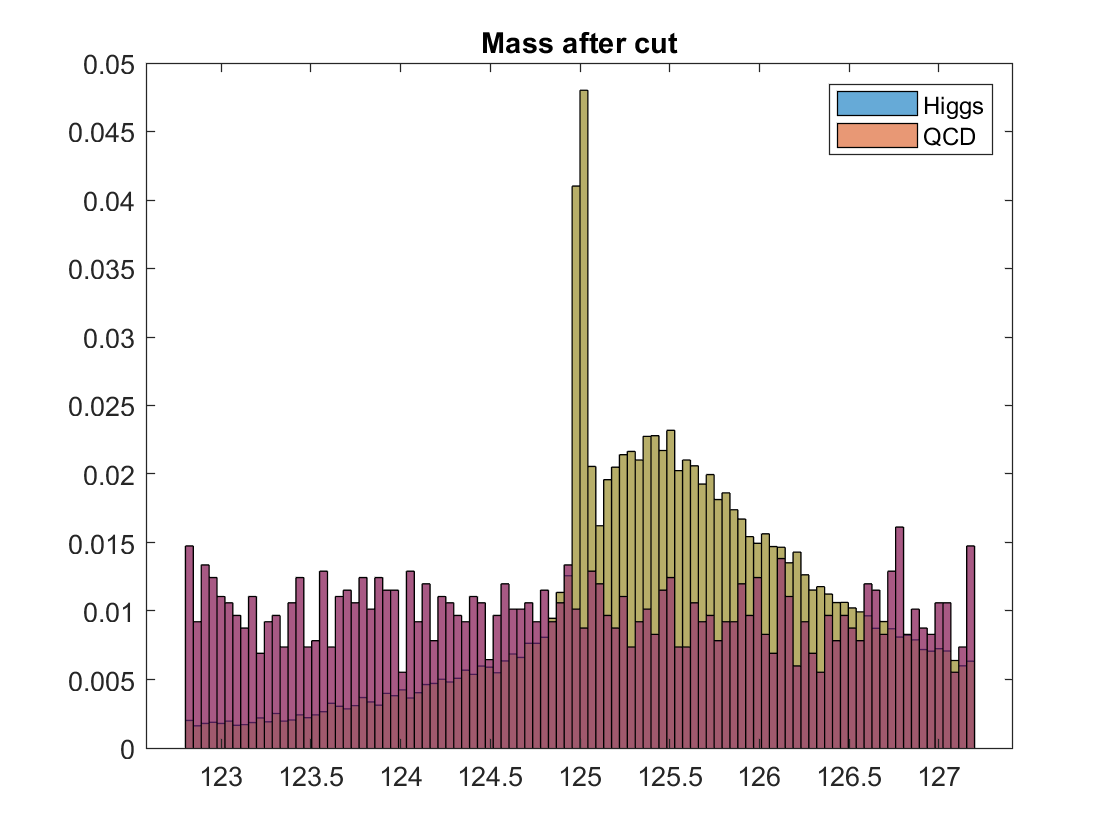

hInvariantMass(hInvariantMass<125-cut) = [];
hInvariantMass(hInvariantMass>125+cut) = [];
qcdInvariantMass(qcdInvariantMass<125-cut) = [];
qcdInvariantMass(qcdInvariantMass>125+cut) = [];

histogram(hInvariantMass, 100, "Normalization","Probability")
hold on
histogram(qcdInvariantMass, 100, "Normalization", "Probability")
hold off
title ("Mass after cut")
legend("show","Higgs","QCD","Location","northeast")

**Problem 3**

hd2 = higgData(7,:);
histogram(hd2,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel '3 to 2 point ECF ratio'
hold on
qcdd2 = qcdData(7,:);
histogram(qcdd2,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

h = [hInvariantMass hd2]
qcd = [qcdInvariantMass qcdd2]